clc;
clearvars;
close all;

% System 1:
num1 = [0 0 1];
den1 = [1 0.2 1];
sys1 = tf(num1, den1)

sys1 =
 
         1
  ---------------
  s^2 + 0.2 s + 1
 
Continuous-time transfer function.



% System 2:
num2 = [0 0.8 1];
den2 = [1 1 1];
sys2 = tf(num2, den2)

sys2 =
 
   0.8 s + 1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



% System 3:
num3 = [0 0 1];
den3 = [1 1 1];
sys3 = tf(num3, den3)

sys3 =
 
       1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



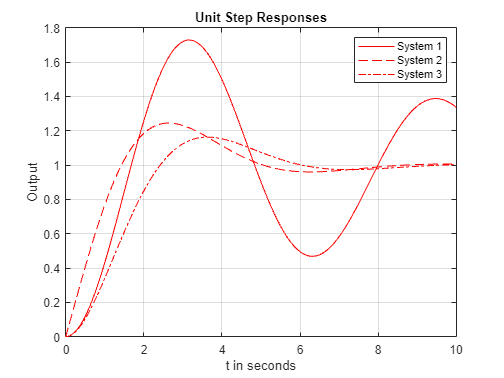

t = 0:0.01:10;
% Plot Step Response
c1 = step(sys1, t);
c2 = step(sys2, t);
c3 = step(sys3, t);

plot(t,c1,'r-');
hold on;
grid on;
title("Unit Step Responses");
xlabel("t in seconds");
ylabel("Output");
plot(t,c2,'r--');
plot(t,c3,'r-.');
legend(["System 1", "System 2", "System 3"]);
hold off;

- With respect to speed of response: System 2 exhibits the shortest rise time

- With respect to maximum overshoot: System 3 exhibits least overshoot

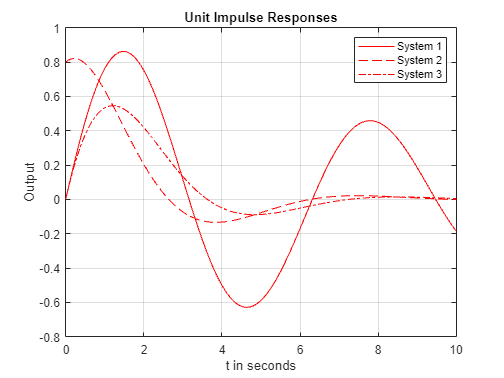

t = 0:0.01:10;
% Plot Impulse Response
c1 = impulse(sys1, t);
c2 = impulse(sys2, t);
c3 = impulse(sys3, t);

plot(t,c1,'r-');
hold on;
grid on;
title("Unit Impulse Responses");
xlabel("t in seconds");
ylabel("Output");
plot(t,c2,'r--');
plot(t,c3,'r-.');
legend(["System 1", "System 2", "System 3"])
hold off;

% System 1:
num1 = [0 0 0 1];
den1 = [1 0.2 1 0];
sys1 = tf(num1, den1);

% System 2:
num2 = [0 0 0.8 1];
den2 = [1 1 1 0];
sys2 = tf(num2, den2);

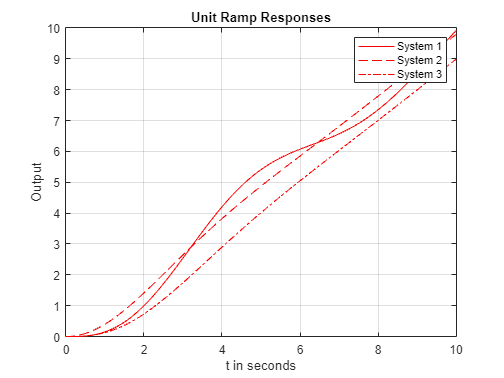

% System 3:
num3 = [0 0 0 1];
den3 = [1 1 1 0];
sys3 = tf(num3, den3);
t = 0:0.01:10;
% Plot Ramp Response
c1 = step(sys1, t);
c2 = step(sys2, t);
c3 = step(sys3, t);

plot(t,c1,'r-');
hold on;
grid on;
title("Unit Ramp Responses");
xlabel("t in seconds");
ylabel("Output");
plot(t,c2,'r--');
plot(t,c3,'r-.');
legend(["System 1", "System 2", "System 3"])
hold off;